# Iterative methods for solving Dirichlet difference problems in a rectangle for the Poisson equation

## Taks 1

% параметри задачі і точність ІП : 
L = [2, 1]; N = [21, 41]; eps = 1e-8; 
% п.1 ІП - метод змінних напрямків (МЗН) з вибором 
%        оптимальних параметрів (ОП) по Жордану  
[n, x, y, Y] = mznopj(L, N, eps, @t82_f, @t82_mx, @t82_my); 

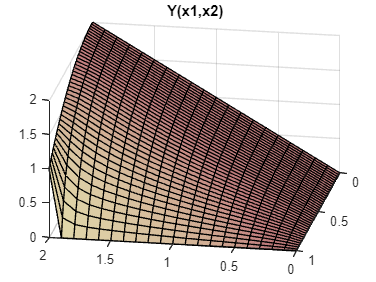

% побудова графіка наближеного розв'язку : 
Uview(x, y, Y, 'Y');

% п.2 ІП - позмінно-трикутний метод (ПТМ) з 
%         чебишовським набором параметрів (ЧНП) 
[n, x, y, Y] = ptmopch(L, N, eps, @t82_f, @t82_mx, @t82_my); 
% побудова графіка наближеного розв'язку : 
Uview(x, y, Y, 'Y');

function f = t82_f(x1, x2) 
    % функція f(x1,x2) : 
    f = x2 .* exp(x1 + x2); 
end

function m = t82_mx(x) 
    % функція  мю(x,y) для y = 0, L(2): 
    m = [x, 0]; 
end 

function m = t82_my(y) 
    % функція  мю(x,y) для x=0, L(1): 
    m = [0, 2 - y * y]; 
end 

function  z = Uview(x, y, U, name) 
    [Yy, Xx] = meshgrid(y, x); 
    surfl(Xx, Yy, U); 
    z = 1; 
    title(strcat(name,'(x1,x2)')); 
    colormap(pink), view(190,30)
end


function [n, x, y, Y] = mznopj(L, N, eps, f, mx, my) 
    % Розв'язування задачі Діріхле в прямокутнику 
    %    П U dП = (0 <= x <= L(1) & 0 <= y <= L(2)) 
    % для рівняння Пуассона за допомогою різницевої схеми з використанням 
    % методу змінних напрямків і вибором оптимальних параметрів по Жордану. 
    %     U"xx + U"yy = -f(x,y),  (x,y) є П, 
    %       U(x,y) = мю(x,y),  (x,y) є dП. 
    % Вхiднi данi : 
    %   L - вектор опису прямокутника; 
    %   N - вектор опису кількості точок сітки; 
    % eps - точність (0<eps<1) ітераційного процесу; 
    %   f - опис функції f(x,y); 
    %  mx - опис функцій мю(x,y), для границь y=0, L(2); 
    %  my - опис функцій мю(x,y), для границь x=0, L(1). 
    % Вихiднi данi: 
    %   n - кількість кроків ітераційного процесу; 
    %   x - сітка по x; 
    %   y - сітка по y; 
    %   Y - сіткова функція наближеного розв'язку U(x,y). 
    % параметри різницевої схеми: 
    Nx = N(1); Nx1 = Nx - 1; x = linspace(0, L(1), Nx); hx = x(2) - x(1); 
    Ny = N(2); Ny1 = Ny - 1; y = linspace(0, L(2), Ny); hy = y(2) - y(1); 

    % формування граничних умов і початкового наближення : 
    Y = zeros(Nx, Ny); 
    for k2 = 1 : Ny 
        z = my(y(k2)); Y(1,k2) = z(1); Y(Nx,k2) = z(2); 
    end 
    for k1 = 2 : Nx1 
        z = mx(x(k1)); Y(k1,1) = z(1); Y(k1,Ny) = z(2); 
    end 
    clear z 

    % обчислення оптимальних ітераційних параметрів : 
    hhx = 1 ./ (hx .* hx); hhy = 1 ./ (hy .* hy); 
    p = 4 .* hhx; ka = 4 .* hhy; t = 0.5 .* pi; 
    r = t .* hx ./ L(1); t = t .* hy ./ L(2); 
    d1 = sin(r); d1 = p .* d1 .* d1; 
    d2 = sin(t); d2 = ka .* d2 .* d2; 
    D1 = cos(r); D1 = p .* D1 .* D1; 
    D2 = cos(t); D2 = ka .* D2 .* D2;  
    ka = (D1 - d1)./(D2 + d1); t = ka .* (D2 - d2); 
    t = sqrt(t ./ (D1 + d2)); eta = (1 - t) ./ (1 + t); 
    ka = ka .* D2 ./ D1; p = (ka - t) ./ (ka + t); 
    r = D1 - D2 + (D1 + D2) .* p; 
    r = 0.5 .* r ./ (D1 .* D2); 
    q = r + (1 - p) ./ D1; 
    n = fix(log(4./eps).*log(4./eta)./(pi.*pi)); 
    tet = eta .* eta; tet = 0.0625.*(1 + 0.5.*tet).*tet; 
    ka = 2 .* n; eta = 0.5 + tet; 

    % формування складових матриць СЛАР : 
    Ax = zeros(Nx, 1); Cx = ones(Nx, 1); Bx = Ax; Fx = Ax; 
    Ay = zeros(Ny, 1); Cy = ones(Ny, 1); By = Ay; Fy = Ay; 
    for j = 1 : n 
        % знаходження компоненти w ітераційних параметрів : 
        t = (2.*j - 1) ./ ka; d1 = eta .* (1 + tet.^t); 
        d2 = 1 + tet.^(1-t) + tet.^(1+t); 
        d2 = tet.^(0.5.*t) .* d2; w = d1./d2;

        % знаходження наближеного розв'язку Y для (j+1/2) : 
        tau = (q .* w + r)./(1 + w .* p); YJ = Y; 
        d1 = tau .* hhx; d2 = 1 + 2 .* d1; 
        D1 = tau .* hhy; D2 = 1 - 2 .* D1; 

        for k1 = 2 : Nx1 
            Ax(k1) = d1; Cx(k1) = d2; Bx(k1) = d1; 
        end 

        for k2 = 2 : Ny1 
            yy = y(k2); 
            Fx(1) = Y(1,k2); Fx(Nx) = Y(Nx,k2); 
            for k1 = 2 : Nx1 
                z = D1 .* (YJ(k1,k2-1) + YJ(k1,k2+1)) + D2 .* YJ(k1,k2); 
                Fx(k1) = z + tau .* f(x(k1), yy); 
            end 
            % розв'язок СЛАР, знаходження Y(:,k2) : 
            [YY, alfa]  =  m_progn(Ax, Cx, Bx, Fx); 
            Y(:,k2) = YY'; 
        end 
        clear YY alfa 

        % знаходження наближеного розв'язку Y для (j+1) : 
        tau = (q .* w - r)./(1 - w .* p); YJ = Y; 
        d1 = tau .* hhy; d2 = 1 + 2 .* d1; 
        D1 = tau .* hhx; D2 = 1 - 2 .* D1; 
        for k2 = 2 : Ny1 
            Ay(k2) = d1; Cy(k2) = d2; By(k2) = d1; 
        end 

        for k1 = 2 : Nx1 
            xx = x(k1); 
            Fy(1) = Y(k1,1); Fy(Ny) = Y(k1,Ny); 
            for k2 = 2 : Ny1 
                z = D1 .* (YJ(k1-1,k2) + YJ(k1+1,k2)) + D2 .* YJ(k1,k2); 
                Fy(k2) = z + tau .* f(xx, y(k2)); 
            end 

            % розв'язок СЛАР, знаходження Y(k1,:) : 
            [YY, alfa]  =  m_progn(Ay, Cy, By, Fy); 
            Y(k1,:) = YY'; 
        end 
        clear YY alfa 
    end 
end 




function [n, x, y, Y] = ptmopch(L, N, eps, f, mx, my) 
    % Розв'язування задачі Діріхле в прямокутнику 
    %    П U dП = (0 <= x <= L(1) & 0 <= y <= L(2)) 
    % для рівняння Пуассона за допомогою різницевої схеми з використанням 
    % позмінно-трикутного методу з чебишовським набором параметрів (ЧНП). 
    %     U"xx + U"yy = -f(x,y),  (x,y) є П, 
    %       U(x,y) = мю(x,y),  (x,y) є dП. 
    % Вхiднi данi : 
    %   L - вектор опису прямокутника; 
    %   N - вектор опису кількості точок сітки; 
    % eps - точність (0<eps<1) ітераційного процесу; 
    %   f - опис функції f(x,y); 
    %  mx - опис функцій мю(x,y), для границь y=0, L(2); 
    %  my - опис функцій мю(x,y), для границь x=0, L(1). 
    % Вихiднi данi: 
    %   n - кількість кроків ітераційного процесу; 
    %   x - сітка по x; 
    %   y - сітка по y; 
    %   Y - сіткова функція наближеного розв'язку U(x,y). 
    % параметри різницевої схеми: 
    Nx = N(1); Nx1 = Nx - 1; x = linspace(0, L(1), Nx); hx = x(2) - x(1); 
    Ny = N(2); Ny1 = Ny - 1; y = linspace(0, L(2), Ny); hy = y(2) - y(1); 
    % формування граничних умов і початкового наближення : 
    Y = zeros(Nx, Ny); YJ = Y; 
    for k2 = 1 : Ny 
        z = my(y(k2)); Y(1,k2) = z(1); Y(Nx,k2) = z(2); 
    end 
    for k1 = 2 : Nx1 
        z = mx(x(k1)); Y(k1,1) = z(1); Y(k1,Ny) = z(2); 
    end 
    clear z 

    % обчислення оптимальних ітераційних параметрів : 
    hhx = 1 ./ (hx .* hx); hhy = 1 ./ (hy .* hy); 
    p = 4 .* hhx; ka = 4 .* hhy; t = 0.5 .* pi; 
    r = t .* hx ./ L(1); t = t .* hy ./ L(2); 
    d = sin(r); d = p .* d .* d; 
    D = sin(t); D = ka .* D .* D; d = d + D; D = p + ka; 
    ka = d ./ D; d2 = sqrt(ka); d1 = 0.5 .* d ./ (1 + d2); 
    d2 = 0.25 .* d ./ d2; w = 2./ sqrt(d .* D); t = d1 ./ d2; 
    r = (1 - t) ./ (1 + t); q = 2 ./ (d1 + d2); 
    n = fix(0.5.*log(2./eps)./sqrt(2.*sqrt(ka))); 
    M = optchset(n); % стійкий набір множини ЧНП 
    d1 = w .* hhx; d2 = w .* hhy; 
    d = 1 ./ (1 + d1 + d2); D = -2 .* (hhx + hhy); 
    for j = 1 : n 
        tau = q ./ (1 + r .* M(j));   % ітераційний параметр 
        for k2 = 2 : Ny1 
            yy = y(k2); 
            for k1 = 2 : Nx1 
                z = hhx .* (Y(k1-1,k2) + Y(k1+1,k2)); 
                p = hhy .* (Y(k1,k2-1) + Y(k1,k2+1));    
                z = z + p + D .* Y(k1,k2) + f(x(k1), yy); 
                p = d1 .* YJ(k1-1,k2) + d2 .* YJ(k1,k2-1); 
                YJ(k1,k2) = (p  + z) .* d; 
            end 
        end 

        for k1 = Nx1 : -1 : 2 
            xx = x(k1); 
            for k2 = Ny1 : -1 : 2 
                z = d1.*YJ(k1+1,k2) + d2.*YJ(k1,k2+1); 
                YJ(k1,k2) = (z + YJ(k1,k2)).*d; 
            end 
        end 

        for k1 = 2: Nx1 
            for k2 = 2 : Ny1 
                Y(k1,k2) = Y(k1,k2) + tau .* YJ(k1,k2);  
            end 
        end 
    end 
end 


function [T] = optchset(n) 
    % Побудова множини оптимальних Чебишовських параметрiв 
    % Вхiднi  данi: 
    %  n - кiлькiсть чисел множини; 
    % Вихiднi данi: 
    %  T - оптимальний набiр параметрiв. 
    % 
    T = nchset(n); b = pi ./ (2.*n); T = -cos(b .* T); 
end 


function [T] = nchset(n) 
    % Побудова множини T(i) непарних чисел для 
    %  оптимальних Чебишовських параметрiв 
    % Вхiднi данi: 
    %  n - кiлькiсть чисел; 
    % Вихiднi данi: 
    %  T - числова множина. 
    P(1) = n; r = n; k=1; 
    while r~=1 
        k = k + 1; 
        if mod(r, 2) == 0 
        r = r ./ 2; 
        else 
        r = r - 1; 
        end 
        P(k) = r; 
    end 

    T(1) = 1; kT = 1; 
    for j = k - 1 : -1 : 1 
        t = r; r = P(j); 
        if 2 .* t == r 
            m = 2 .* r; 
            if j ~= 1 
                if P(j-1) == r + 1 
                    m = m + 2; 
                end 
            end     
            for i = t : -1 : 1 
                i2 = 2 .* i; e = T(i); 
                T(i2 - 1) = e; T(i2) = m - e; 
            end 
            kT = kT .* 2; 
        else 
            kT = kT + 1; T(kT) = r; 
        end 
    end 
end 


function [y, alfa]  =  m_progn(a, c, b, f)  
    n = length(c); n1 = n - 1; 
    % пряма прогонка: 
    alfa = zeros(1, n); y = alfa; 
    beta = alfa; ka = ones(1, n); te = alfa; 
    C = c(1); A = a(2); F = f(1); Q = f(2); 
    for k = 1 : n1 
        j = k + 1; 
        if abs(C) >= abs(b(k)) 
            alfa(j) = b(k) ./ C; beta(j) = F ./ C; 
            C = c(j) - A .* alfa(j); F = Q + A .* beta(j); 
            te(j) = ka(k); ka(j) = j; 
            if k ~= n1 
                j = j + 1; A = a(j); Q = f(j); 
            end 
        else 
            alfa(j) = C ./ b(k); beta(j) = -F ./ b(k); 
            C = c(j) .* alfa(j) - A; F = Q - c(j) .* beta(j); 
            te(j) = j; ka(j) = ka(k); 
            if k ~= n1 
                j1 = j; j = j + 1; 
                A = a(j) .* alfa(j1); Q = f(j) + a(j) .* beta(j1); 
            end 
        end   
    end 
    % зворотня прогонка: 
    y(ka(n)) =F ./ C; 
    for k=n1 : -1 : 1 
        j = k + 1; y(te(j)) = alfa(j) .* y(ka(j)) + beta(j); 
    end 
end 